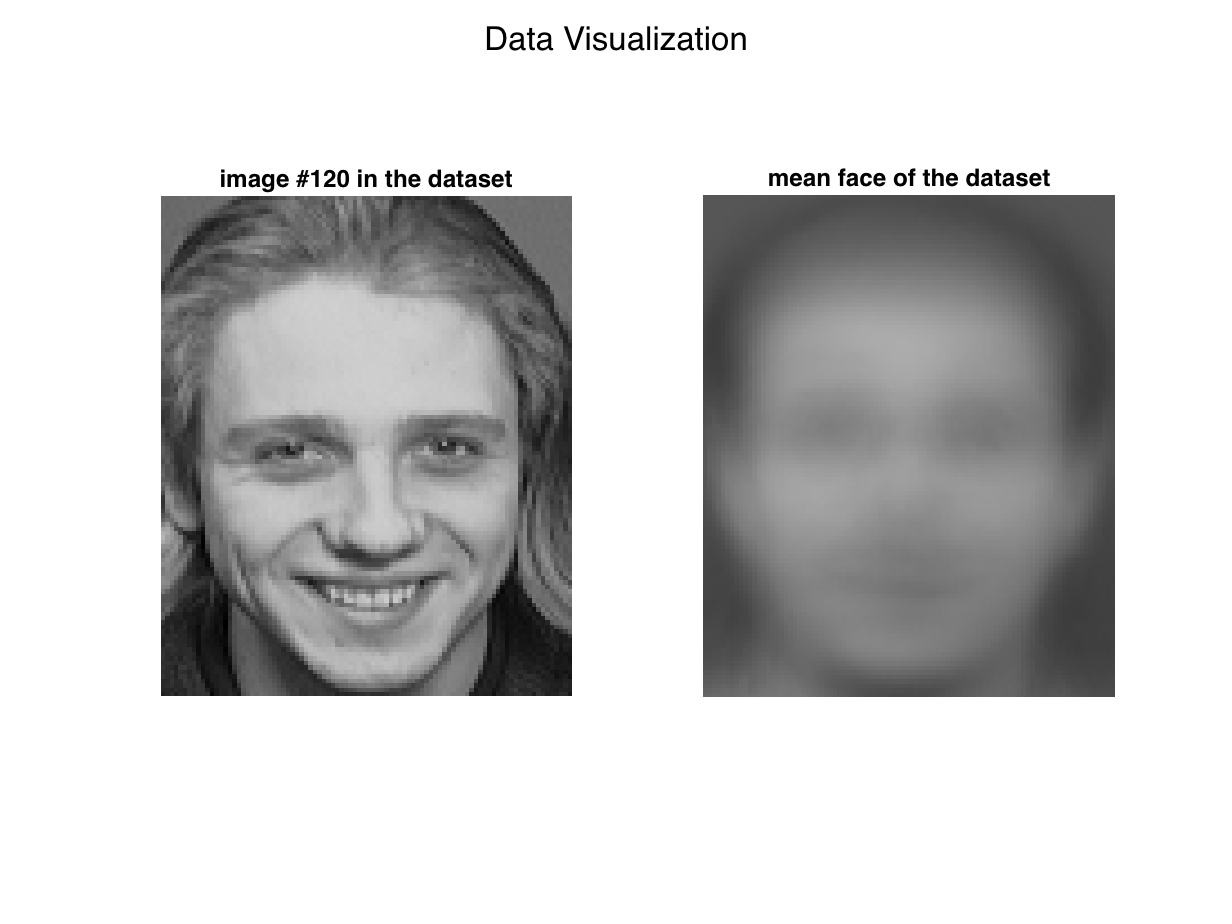

%function [lambda_top5, k_] = skeleton_hw5_2()
%% Q5.2
%% Load AT&T Face dataset
    img_size = [112,92];   % image size (rows,columns)
    % Load the AT&T Face data set using load_faces()
    %%%%% TODO
    faces = load_faces();
    X = faces'; %d x n fature matrix
    [d,n] = size(X);
    one_n = ones(n,1); %n x 1 "all ones" vector
    %mu_x = (1/n) * X * one_n; %d x 1 empirical mean feature vector
    %mu_x = (1/n) * sum(X,2); %d x 1 empirical mean feature vector
    mu_x = mean(X,2);
    %% Compute mean face and the covariance matrix of faces
    % compute X_tilde1
    X_tilde = X - mu_x * one_n'; %d x n mean-centered feature matrix
    
    % Compute covariance matrix using X_tilde
    Sx = (1/n) * X_tilde * X_tilde'; %d x d empirical covariance matrix of feature vectors
    
    %% Compute the eigenvalue decomposition of the covariance matrix
    [V,D] = eig(X_tilde' * X_tilde); %diagonal matrix D of eigenvalues and matrix V whose columns are the corresponding right eigen vectors
    
    %% Sort the eigenvalues and their corresponding eigenvectors construct the U and Lambda matrices
    [ds,ind] = sort(diag(D),'descend');
    Ds = D(ind,ind);
    Vs = V(:,ind);
    
    U = zeros(d,d);
    for i = 1:n
        U(:,i) = (1/sqrt(ds(i))) * X_tilde * Vs(:,i);
    end
    Lambda = zeros(d,d);
    Lambda(1:n,1:n) = (1/n) * Ds;
    %% Compute the principal components: Y
    %%%%% TODO
    WPCA = U;
    yPCA = WPCA' * (X - mu_x);
%% Q5.2 a) Visualize the loaded images and the mean face image
    figure(1)
    sgtitle('Data Visualization')
    
    % Visualize image number 120 in the dataset
    % practice using subplots for later parts
    subplot(1,2,1)
    imshow(uint8(reshape(X(:,120)', img_size)));
    title('image #120 in the dataset')
    
    % Visualize the mean face image
    subplot(1,2,2)
    imshow(uint8(reshape(mu_x', img_size)));
    title('mean face of the dataset')

    
    fprintf('The mean face resembles a smooth shapeless "blob"\n');

The mean face resembles a smooth shapeless "blob"


%% Q5.2 b) Analysing computed eigenvalues
    warning('off')
    
    % Report the top 5 eigenvalues
    lambda_top5 = ds(1:5);
    fprintf('The first five eigenvalues are\n');

The first five eigenvalues are


    disp(lambda_top5);

   1.0e+09 *

    1.1267
    0.8258
    0.4377
    0.3570
    0.3270



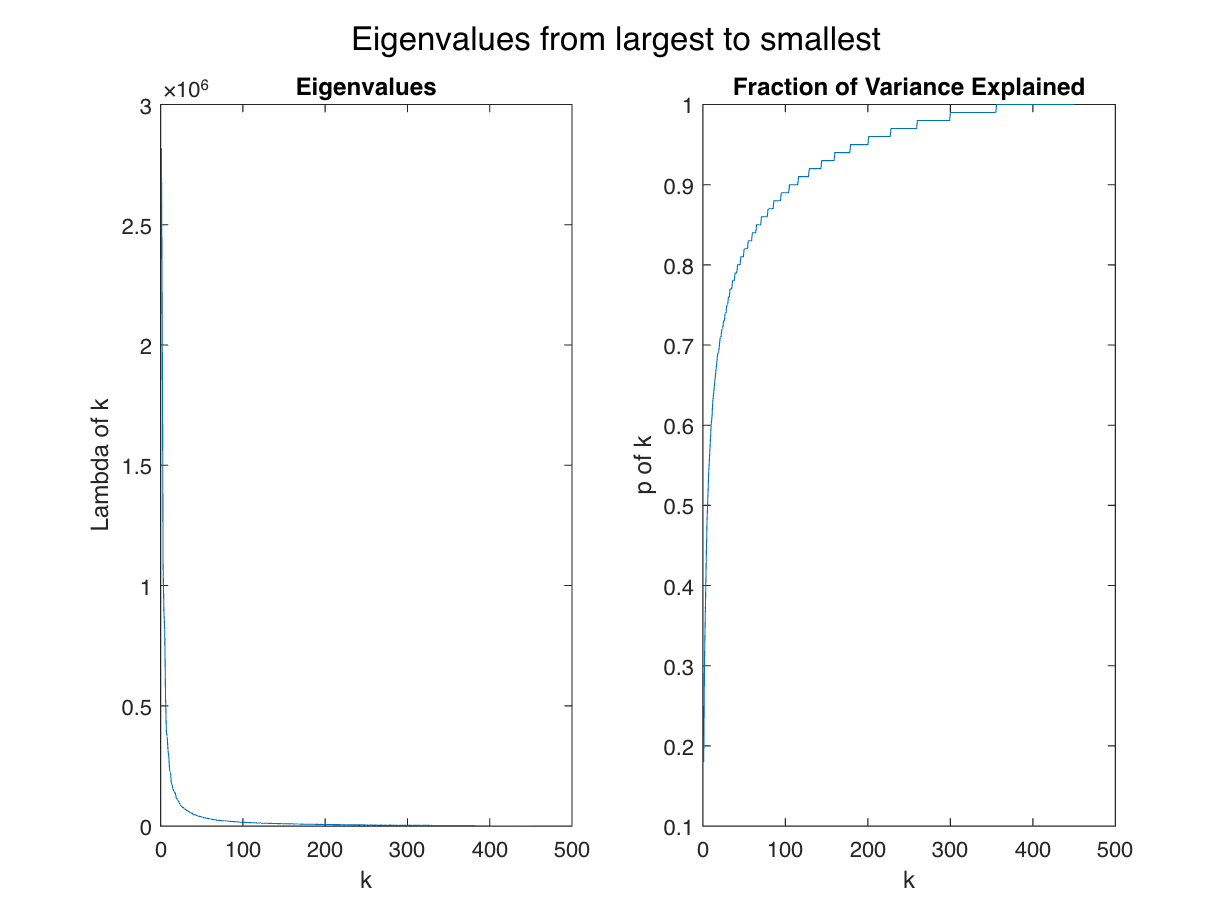

    
    % Plot the eigenvalues in from largest to smallest
    d = 450;
    k = 1:d;
    Lambdas = diag(Lambda);
    figure(2)
    hold on
    sgtitle('Eigenvalues from largest to smallest')

    % Plot the eigenvalue number k against k
    subplot(1,2,1);
    plot(k,Lambdas(1:d));
    title('Eigenvalues');
    xlabel('k');
    ylabel('Lambda of k');
    
    % Plot the sum of top k eigenvalues, expressed as a fraction of the sum of all eigenvalues, against k
    %%%%% TODO: Compute eigen fractions
    p = zeros(d,1);
    for i = k
        p(i) = sum(Lambdas(1:i))/sum(Lambdas(1:d));
    end
    p = round(p,2);
    subplot(1,2,2);
    plot(k,p);
    title('Fraction of Variance Explained');
    xlabel('k');
    ylabel('p of k');
    hold off

    
    % find & report k for which the eigen fraction = [0.51, 0.75, 0.9, 0.95, 0.99]
    ef = [0.51, 0.75, 0.9, 0.95, 0.99];
    [li_ef, loc_p] = ismember(ef,p);
    k_ = loc_p;

    fprintf('The smallest values of k for which ρk ≥ 0.51, 0.75, 0.90, 0.95, and 0.99 \n');

The smallest values of k for which ρk ≥ 0.51, 0.75, 0.90, 0.95, and 0.99 


    disp(k_);

     6    29   105   179   300



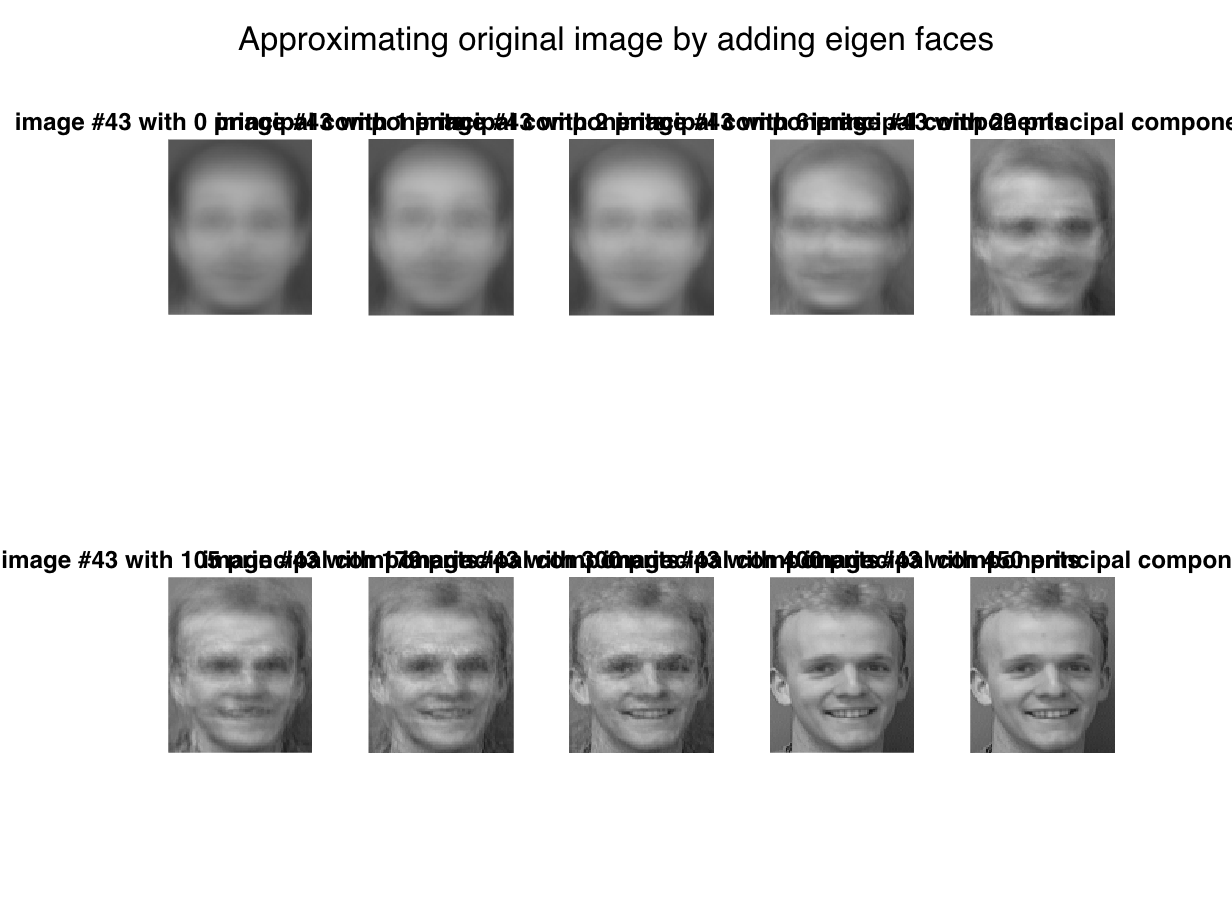

    
%% Q5.2 c) Approximating an image using eigen faces
    test_img_idx = 43;
    test_img = X(:,test_img_idx);    
    % Compute eigenface coefficients
%     ypca = zeros(10304,d);
%     for i = 1:d
%         ypca(:,i) = dot((test_img - mu_x),U(:,i));
%     end
    
    K = [0,1,2,k_,400,d];
    pca = zeros(10304,length(K));
    for i = 1:length(K)
        sumpca = zeros(10304,1);
        for j = 1:K(i)
            u = U(:,j);
            ypca = u' * (test_img - mu_x);
            sumpca = sumpca + (ypca * u);
        end
        pca(:,i) = mu_x + sumpca;
    end
    % add eigen faces weighted by eigen face coefficients to the mean face
    % for each K value
    % 0 corresponds to adding nothing to the mean face

    % visulize and plot in a single figure using subplots the resulating image approximations obtained by adding eigen faces to the mean face.

    %%%% TODO 
    
    figure(3)
    sgtitle('Approximating original image by adding eigen faces')
    hold on
    for i = 1:length(K)
        subplot(2,5,i)
        imshow(uint8(reshape(pca(:,i)', img_size)));
        titl = sprintf('image #43 with %d principal components',K(i));
        title(titl);
    end
    hold off

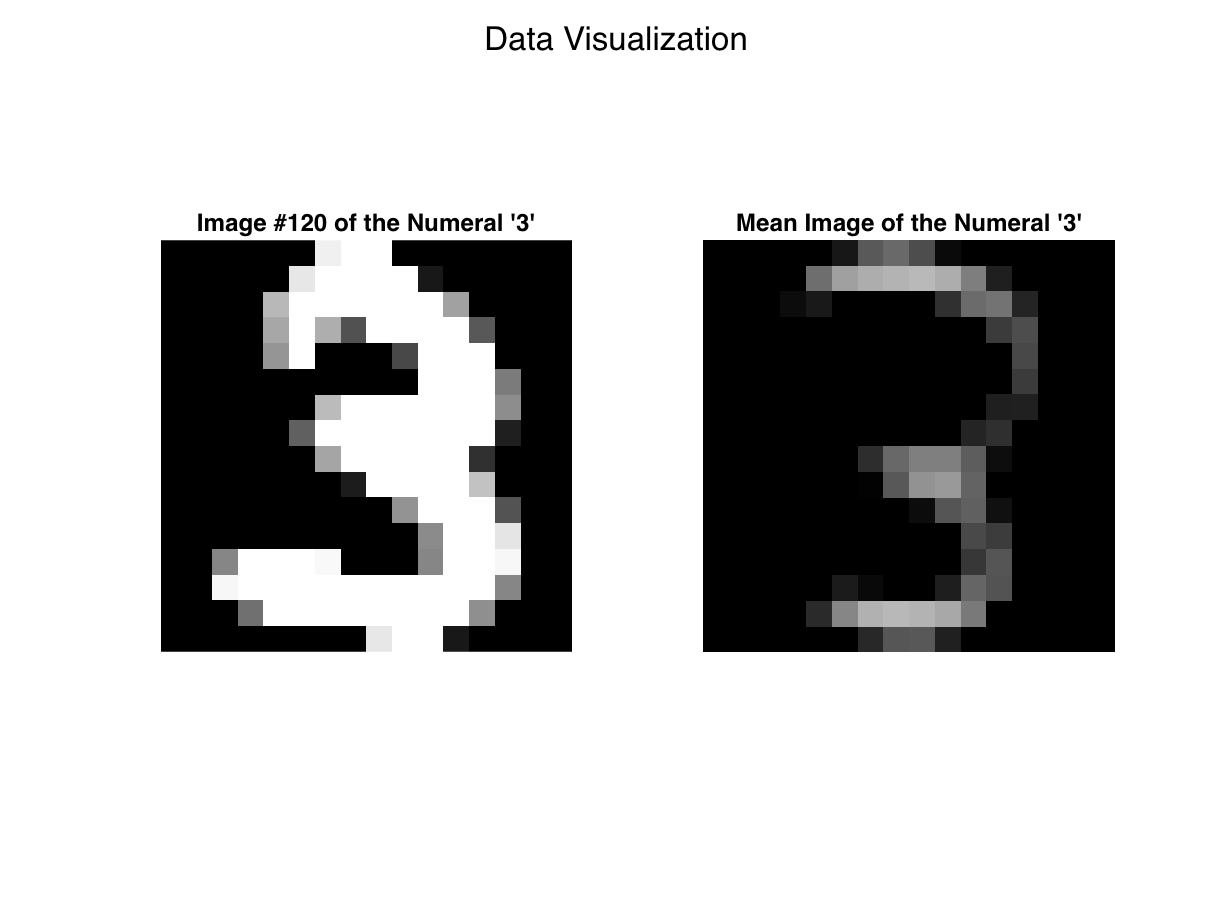

%% Q5.2 d) Principal components capture different image characteristics
%% Loading and pre-processing MNIST Data-set
    % Data Prameters
    q = 5;                  % number of percentile points
    noi = 3;                % Number of interest
    img_size = [16, 16];
    
    % load mnist into workspace
    mnist = load('mnist256.mat').mnist;
    label = mnist(:,1);
    X = mnist(:,(2:end));
    num_idx = (label == noi);
    X = X(num_idx,:);
    %[n,~] = size(X);
    
    X = X'; %d x n fature matrix
    [d,n] = size(X);
    one_n = ones(n,1); %n x 1 "all ones" vector
    %mu_x = (1/n) * X * one_n; %d x 1 empirical mean feature vector
    %mu_x = (1/n) * sum(X,2); %d x 1 empirical mean feature vector
    mu_x = mean(X,2);
    %% Compute mean face and the covariance matrix of faces
    % compute X_tilde1
    X_tilde = X - mu_x * one_n'; %d x n mean-centered feature matrix
    
    % Compute covariance matrix using X_tilde
    Sx = (1/n) * X_tilde * X_tilde'; %d x d empirical covariance matrix of feature vectors
    
    %% Compute the eigenvalue decomposition of the covariance matrix
    [V,D] = eig(X_tilde' * X_tilde); %diagonal matrix D of eigenvalues and matrix V whose columns are the corresponding right eigen vectors
    
    %% Sort the eigenvalues and their corresponding eigenvectors construct the U and Lambda matrices
    [ds,ind] = sort(diag(D),'descend');
    Ds = D(ind,ind);
    Vs = V(:,ind);
    
    U = zeros(d,d);
    for i = 1:n
        U(:,i) = (1/sqrt(ds(i))) * X_tilde * Vs(:,i);
    end
    Lambda = zeros(d,d);
    Lambda(1:n,1:n) = (1/n) * Ds;
    
    %% Compute principal components
    %%%%% TODO
    
    %% Computing the first 2 pricipal components
    first_ypca = zeros(1,n);
    for i = 1:n
        u = U(:,1);
        first_ypca(i) = u' * (X(:,i) - mu_x);
    end
    second_ypca = zeros(1,n);
    for i = 1:n
        u = U(:,2);
        second_ypca(i) = (u' * (X(:,i) - mu_x));
    end

    % finding percentile points
    percentile_vals = [5, 25, 50, 75, 95];
    %%%%% TODO (Hint: Use the provided fucntion - percentile_points())
    %pv_1 = zeros(5,)
    pv_1 = percentile_values(first_ypca',percentile_vals);
    pv_2 = percentile_values(second_ypca',percentile_vals);
    % Finding the cartesian product of percentile points to find grid corners
    [x,y] = meshgrid(pv_1,pv_2);
    result = [x(:) y(:)];

    %[A{1:2}] = ngrid([pv_1' pv_2']);
    %G(:,1) = A{1}(:);
    %G(:,2) = A{2}(:);
    %result = unique(G,'rows');
    
    
    %% Find images whose PCA coordinates are closest to the grid coordinates 
    [k,dist] = dsearchn([first_ypca' second_ypca'],result);
    %%%%% TODO

    %% Visualize loaded images
    % random image in dataset
    figure(4)
    hold on
    sgtitle('Data Visualization')

    % Visualize the 120th image
    subplot(1,2,1)
    imshow((reshape(X(:,120)', img_size)));
    title('Image #120 of the Numeral ''3''');
    
    % Mean image of the numeral '3'
    subplot(1,2,2)
    imshow((reshape(mu_x', img_size)));
    title('Mean Image of the Numeral ''3''');
    hold off

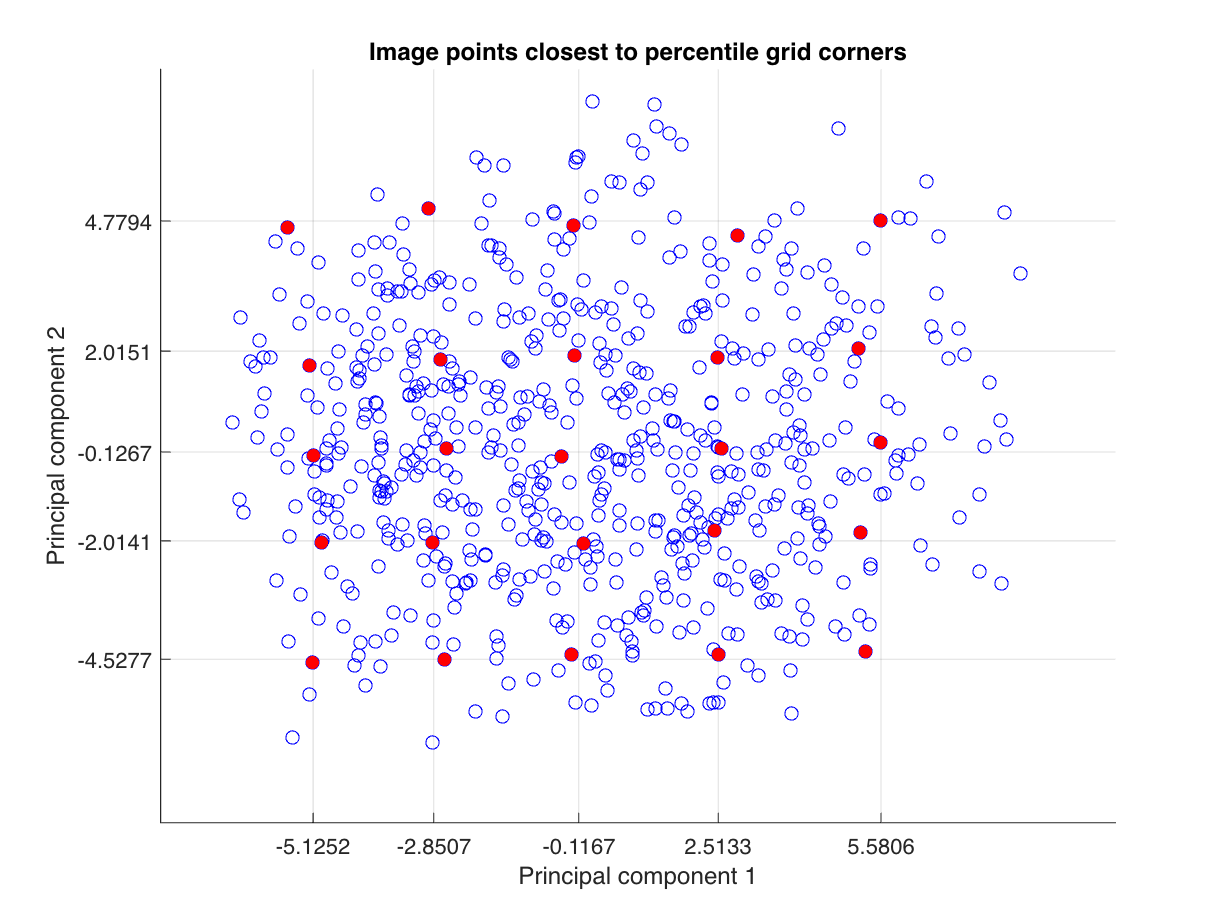

    %% Image projections onto principal components and their corresponding features
    
    figure(5)    
    hold on
    grid on
    
    % Plotting the principal component 1 vs principal component 2. Draw the
    % grid formed by the percentile points and highlight the image points that are closest to the 
    % percentile grid corners
    
    %%%%% TODO (hint: Use xticks and yticks)
    scatter(first_ypca,second_ypca,'ob')
    xlabel('Principal component 1')
    ylabel('Principal component 2')
    title('Image points closest to percentile grid corners')
    xticks(sort(pv_1))
    yticks(sort(pv_2))
    scatter(first_ypca(k),second_ypca(k),'or','filled');
    %scatter(result(:,1),result(:,2),'*g')
    hold off

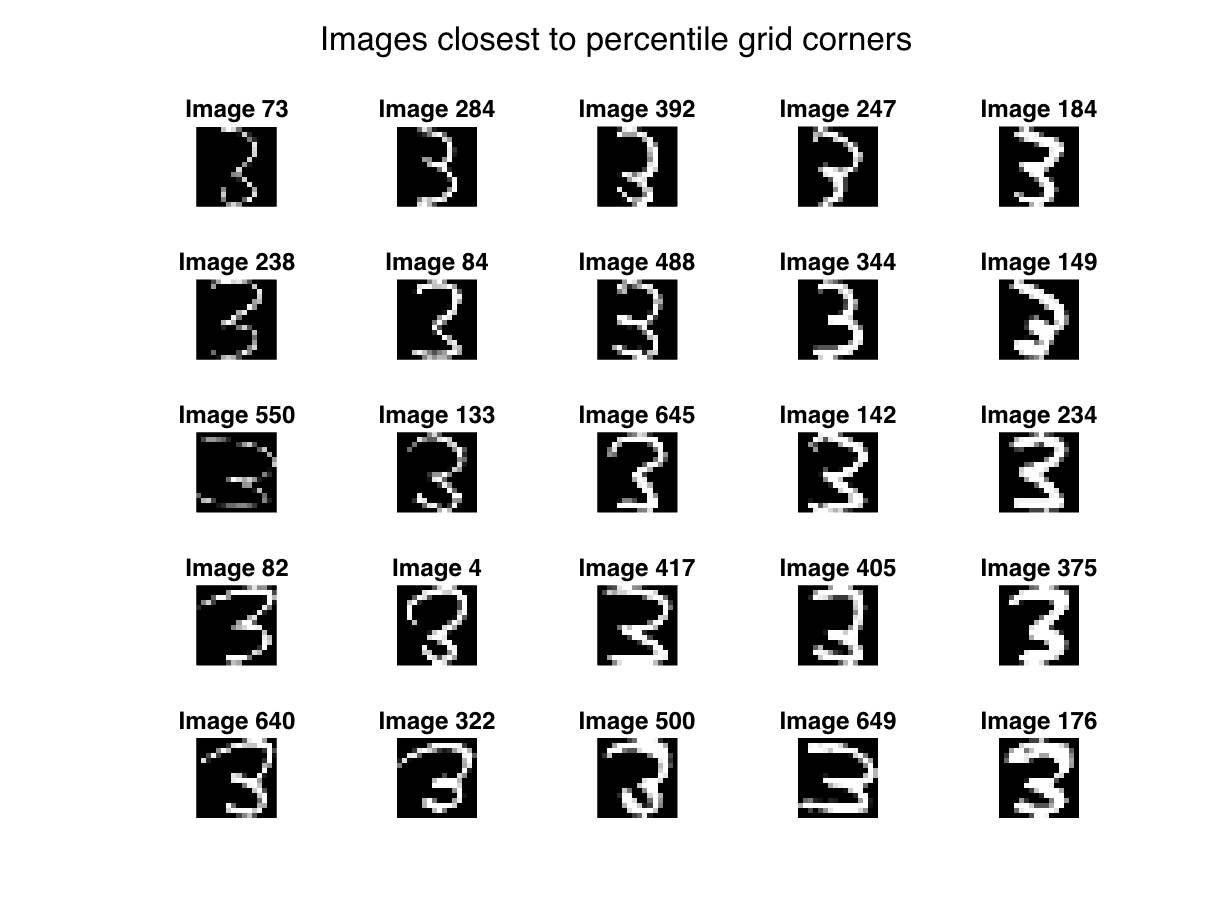

    
    figure(6)
    sgtitle('Images closest to percentile grid corners')
    hold on
    % Plot the images whose PCA coordinates are closest to the percentile grid 
    % corners. Use subplot to put all images in a single figure in a grid.
    %k = sort(k);
    for i = 1:length(k)
        subplot(5,5,i)
        imshow((reshape(X(:,k(i)), img_size)));
        titl = sprintf('Image %d',k(i));
        title(titl);
    end
    %%%%% TODO
    
    hold off    

%end
